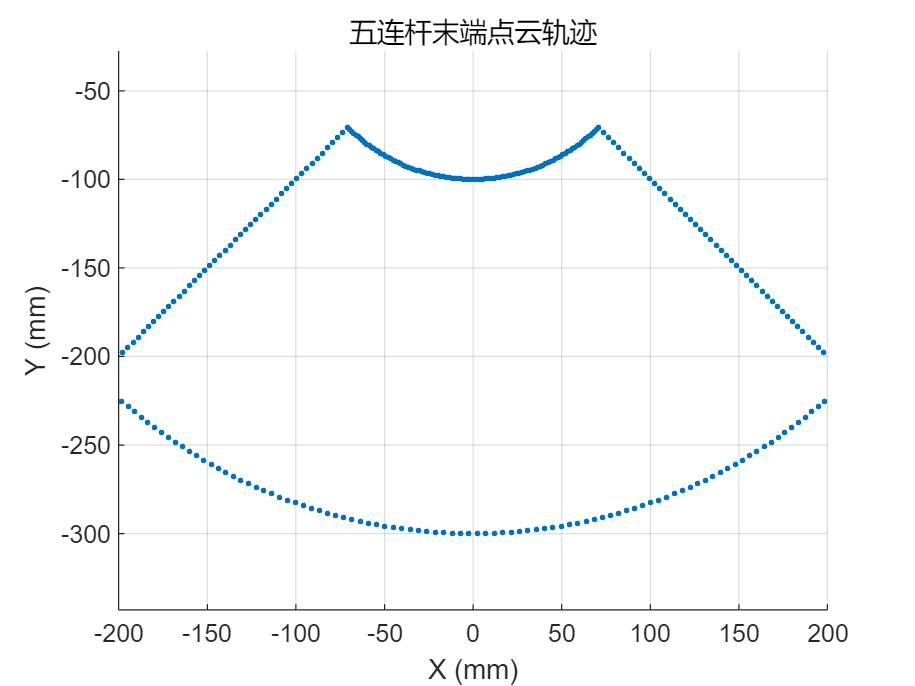

% 扇环参数
sector = struct(...
    'r_min', 100,...   % 内半径
    'r_max', 300,...   % 外半径
    'theta_min', deg2rad(-135),...  % 起始角度（弧度）
    'theta_max', deg2rad(-45)...  % 终止角度（弧度）
);

% 生成角度范围（用于圆弧）
theta_range = linspace(sector.theta_min, sector.theta_max, 100); % 100个点

% 计算外环边界点
x_outer = sector.r_max * cos(theta_range);
y_outer = sector.r_max * sin(theta_range);

% 计算内环边界点（逆序）
x_inner = sector.r_min * cos(fliplr(theta_range)); 
y_inner = sector.r_min * sin(fliplr(theta_range));

% 计算半径上的点
num_radial_points = 50; % 半径方向上的点数量
r_values = linspace(sector.r_min, sector.r_max, num_radial_points);

% 计算 θ_min 角度方向上的径向点
x_radial_min = r_values * cos(sector.theta_min);
y_radial_min = r_values * sin(sector.theta_min);

% 计算 θ_max 角度方向上的径向点
x_radial_max = r_values * cos(sector.theta_max);
y_radial_max = r_values * sin(sector.theta_max);

% 组合所有边界点
x_boundary = [x_outer, x_radial_max, x_inner, fliplr(x_radial_min)];
y_boundary = [y_outer, y_radial_max, y_inner, fliplr(y_radial_min)];
figure;
scatter(x_boundary,y_boundary,5,'filled');
xlabel('X (mm)'); ylabel('Y (mm)');
title('五连杆末端点云轨迹');
xlim([-200,200])
ylim([-350,-100])
axis equal;
grid on;

% 预处理：预先计算角度边界的三角函数值以加速计算
sector.sin_theta_min = sin(sector.theta_min);
sector.cos_theta_min = cos(sector.theta_min);
sector.sin_theta_max = sin(sector.theta_max);
sector.cos_theta_max = cos(sector.theta_max);
% 计算扇区面积
sector_area = (sector.r_max^2 - sector.r_min^2)*(sector.theta_max-sector.theta_min)/2

sector_area = 6.2832e+04

area_in = 6.3118e+04

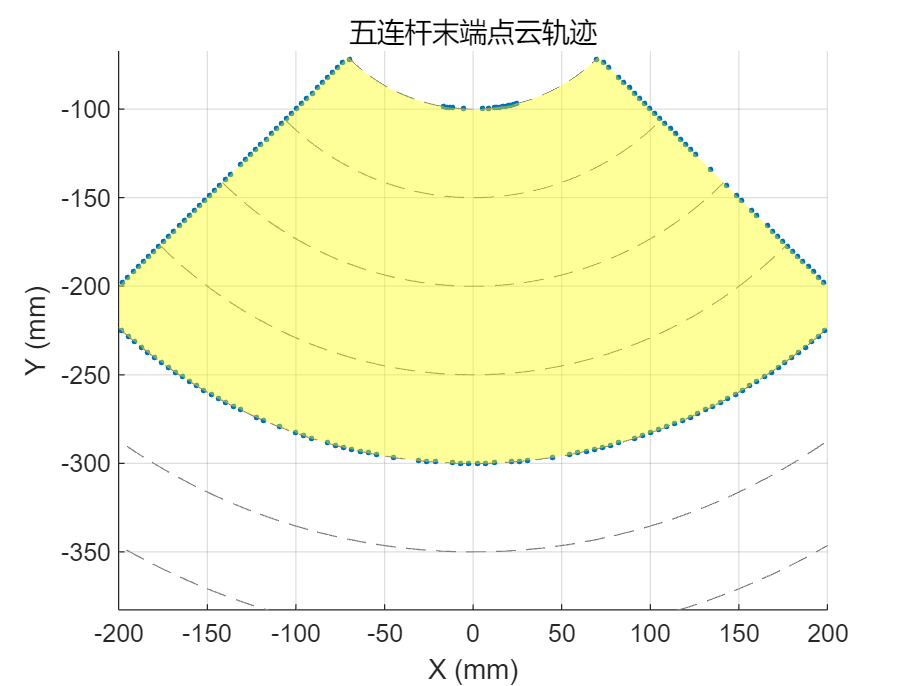

r=load('data\all_results.mat');
scores = zeros(1, 1, 'single');
% scores=evaluateSectorOptimized(r.results{10649}.F_x, r.results{10649}.F_y, sector, 0,sector_area);
scores=evaluateSectorOptimized(x_boundary', y_boundary', sector, 0,sector_area);

function score = evaluateSectorOptimized(F_x, F_y, sector, useGPU, area)
% 数据传输（保持原有GPU处理逻辑）
if useGPU
    F_x = gpuArray(F_x);
    F_y = gpuArray(F_y);
end
% 快速筛选逻辑（保持原有筛选条件）
r_sq = F_x.^2 + F_y.^2;
valid_r = (r_sq >= sector.r_min^2) & (r_sq <= sector.r_max^2);
cross_min = F_x * sector.sin_theta_min - F_y * sector.cos_theta_min;
cross_max = F_x * sector.sin_theta_max - F_y * sector.cos_theta_max;
valid_theta = (cross_min <= 0) & (cross_max >= 0);
valid_mask = valid_r & valid_theta;

Fx_in = F_x(valid_mask);
Fy_in = F_y(valid_mask);
% figure;
% scatter(Fx_in,Fy_in,5,'filled');
% hold on;
% 改进的面积计算
if numel(Fx_in) < 3
    area_in = 0;
else
    % 极角
    shp = alphaShape(double(Fx_in), double(Fy_in)); 
    shp.Alpha=criticalAlpha(shp,'one-region');

    [~,by] = boundaryFacets(shp);  % 获取边界点
    Fx_in=by(:,1);
    Fy_in=by(:,2);
    center_x = mean(Fx_in);
    center_y = mean(Fy_in);
    % 计算相对质心的极角
    [~, idx] = sort(atan2(Fy_in - center_y, Fx_in - center_x));
    sorted_x = Fx_in(idx);
    sorted_y = Fy_in(idx);                
    % 多边形面积公式
    x_shift = circshift(sorted_x, -1);
    y_shift = circshift(sorted_y, -1);
    area_in = 0.5 * abs(sum(sorted_x.*y_shift - x_shift.*sorted_y))
end
figure;
scatter(by(:,1),by(:,2),5,'filled');
hold on;

% Plot the circles
for r = 100:50:450
    theta = linspace(5*pi/4, 7*pi/4, 1000); % 足够多的点使曲线平滑
    x = r * cos(theta);
    y = r * sin(theta);
    plot(x, y, 'Color', [0.5 0.5 0.5], 'LineStyle', '--'); % 灰色虚线
end

% Add the transparent fan ring
theta_fan = linspace(1.25*pi, 1.75*pi, 100); % Angular range from 1.25pi to 1.75pi
r_inner = 100; % Inner radius
r_outer = 300; % Outer radius

% Coordinates for the inner and outer edges of the fan ring
x_inner = r_inner * cos(theta_fan);
y_inner = r_inner * sin(theta_fan);
x_outer = r_outer * cos(theta_fan);
y_outer = r_outer * sin(theta_fan);

% Create the filled sector (fan ring) by connecting the inner and outer edges
fill([0, x_outer, fliplr(x_inner)], [0, y_outer, fliplr(y_inner)], 'y', 'FaceAlpha', 0.4, 'EdgeColor', 'none');

hold off;
xlabel('X (mm)'); ylabel('Y (mm)');
title('五连杆末端点云轨迹');
xlim([-200,200])
ylim([-350,-100])
axis equal;
grid on;
    % 得分计算
    score = 1;%max(0, gather(area_in/area));
end